# Analyse Déplacement Prédéterminé - Donnée Fabriquer

Ce fichier présente l'application de notre filtre Kaman faisant parti de notre approche présenté. Afin de garder les choses simples et de bien comprendre son principe, nous avons générer un ensemble de valeurs d'accélération représentant un déplacement prédéterminé. 

## Fabrication des valeurs d'accélération à partir d'un déplacement prédéterminé

close all;                    % fermeture de tous les figures
clear;                        % effacer tous les variables
clc;                          % effacer tous les commandes du terminal

dt = 0.1;             %période d'échantillonnage de 100ms
numSample = 50.0 / dt;%nombre d'échantillon pour une durée de 50sec

accel = zeros(numSample, 2);
vitesse = zeros(numSample, 2);
position = zeros(numSample, 2);

Précalculer le vecteur de temps en additionnant la période d'échantillonnage de 100ms

for i = 2:numSample
    accel(i, 2) = accel(i-1, 2) + dt;
end
vitesse(:,2) = accel(:, 2);
position(:,2) = accel(:, 2);

sampleTime = 10.0;
numAccelSample = sampleTime / dt;


Générer les échantillons d'accélération pour une déplacement vers l'avant de 10cm

up  = genSampleAccelData(sampleTime, dt, 0.1);

Générer les échantillons d'accélération pour une déplacement vers l'arrière de 10cm

down  = genSampleAccelData(sampleTime, dt, -0.1);

Insérer les échantillons de déplacement avant et arrière à l'intérieur de l'ensemble des échantillons

accel(numAccelSample+1:numAccelSample+numAccelSample, 1) = up(:,1);
accel(3*numAccelSample+1:3*numAccelSample+numAccelSample, 1) = down(:,1);

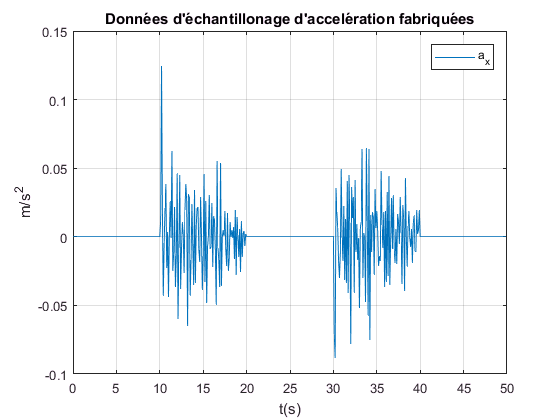

figure
plot(accel(:,2), accel(:,1));
title 'Données d''échantillonage d''accelération fabriquées';
legend 'a_x';
grid 'on';
ylabel 'm/s^2';
xlabel 't(s)';

Calcule de la vitesse au temps t selon la formule d'intégration suivante : $\mathbf{v}{\left(\mathbf{t}\right)}=\mathbf{ }\mathbf{v}{\left(0\right)}\text{ }+\int_0^{\mathbf{t}} \mathbf{a}{\left(\mathbf{t}\right)}\mathbf{ }\mathbf{d}\mathbf{t}$ 

Équivalente à l'approximation numérique suivante :$\mathbf{ }\mathbf{v}{\left(\mathbf{t}+\mathbf{ }\mathit{\mathbf{\delta }}\mathbf{t}\right)}=\mathbf{ }\mathbf{v}{\left(\mathbf{t}\right)}+\mathbf{ }\mathbf{a}{\left(\mathbf{t}+\mathbf{ }\mathit{\mathbf{\delta }}\mathbf{t}\right)}\text{∙}\mathit{\mathbf{\delta }}\mathbf{t}$

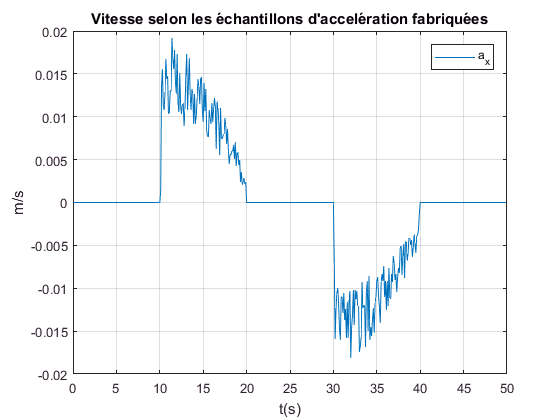

for i = 2:numSample
    if(accel(i,1) ~= 0.0)
        vitesse(i, 1) = vitesse(i-1, 1) + accel(i,1)*dt;
    else
        vitesse(i, 1) = 0.0;
    end
end

figure
plot(vitesse(:,2), vitesse(:,1));
title 'Vitesse selon les échantillons d''accelération fabriquées';
legend 'a_x';
grid 'on';
ylabel 'm/s';
xlabel 't(s)';

Calcule de la position au temps t selon la formule d'intégration suivante : $\mathbf{s}{\left(\mathbf{t}\right)}=\mathbf{ }\mathbf{s}{\left(0\right)}+\mathbf{ }\int_0^{\mathbf{t}} \mathbf{v}{\left(\mathbf{t}\right)}\mathbf{ }\mathbf{d}\mathbf{t}$ équivalent à l'approximation numérique suivante :$\mathbf{ s}{\left(\mathbf{t}+\mathbf{ }\mathit{\mathbf{\delta }}\mathbf{t}\right)}=\mathbf{s}{\left(\mathbf{t}\right)}+\mathbf{ v}\left(\mathbf{t}+\mathbf{ }\mathit{\mathbf{\delta }}\mathbf{t}\right)\text{∙}\mathit{\mathbf{\delta }}\mathbf{t}\mathbf{ }$

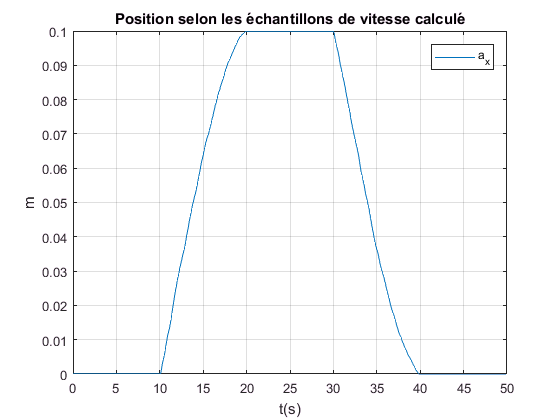

for i = 2:numSample
    position(i, 1) = position(i-1, 1) + vitesse(i,1)*dt;
end

figure
plot(position(:,2), position(:,1));
title 'Position selon les échantillons de vitesse calculé';
legend 'a_x';
grid 'on';
ylabel 'm';
xlabel 't(s)';